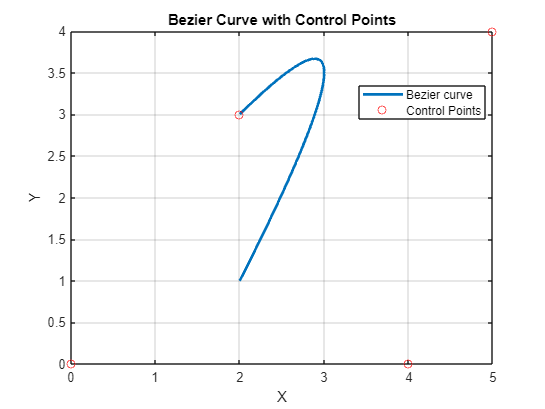

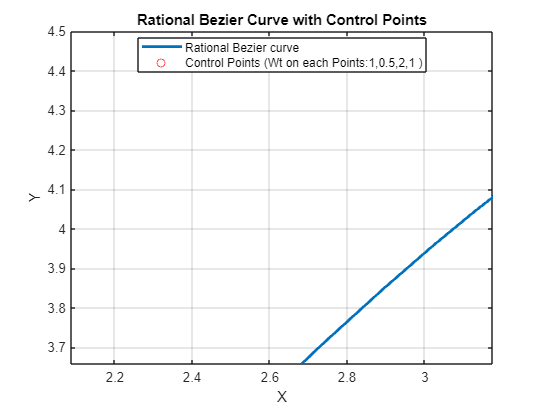

% Read data from the first text file (Bazier curve)
data1 = dlmread('bazier_output.txt');

% Extract x and y coordinates for the first curve
x1 = data1(:, 1);
y1 = data1(:, 2);

% Additional control points for the first curve
control_points_1 = [0, 0; 2, 3; 4, 0; 5, 4];

% Plot the first curve with its control points and join control points sequentially
figure;
plot(x1, y1, 'LineWidth', 2);
hold on; % Keep the current plot
scatter(control_points_1(:, 1), control_points_1(:, 2), 'ro'); % Plotting control points as red circles
% for i = 1:size(control_points_1, 1)-1
%     plot(control_points_1(i:i+1, 1), control_points_1(i:i+1, 2), '--', 'Color', [0.5, 0.5, 0.5]); % Joining control points with faint dashed lines
% end
% hold off; % Release the hold on the plot

xlabel('X');
ylabel('Y');
title('Bezier Curve with Control Points');
legend('Bezier curve', 'Control Points', 'Location', 'best');
grid on;